#### 1

Normelized and grayscale Mona images:

original_image=dip_GN_imread("img\pzl_6_1.jpg");
not_origianl=dip_GN_imread("img\pzl_6_2.jpg");

#### 2

points_origianl=detectSURFFeatures(original_image);
points_not_original=detectSURFFeatures(not_origianl);

[f1,vpts1] = extractFeatures(original_image,points_origianl);
[f2,vpts2] = extractFeatures(not_origianl,points_not_original);

Find the locations of matched points.

indexPairs = matchFeatures(f1,f2) ;
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));

Display the matching points.

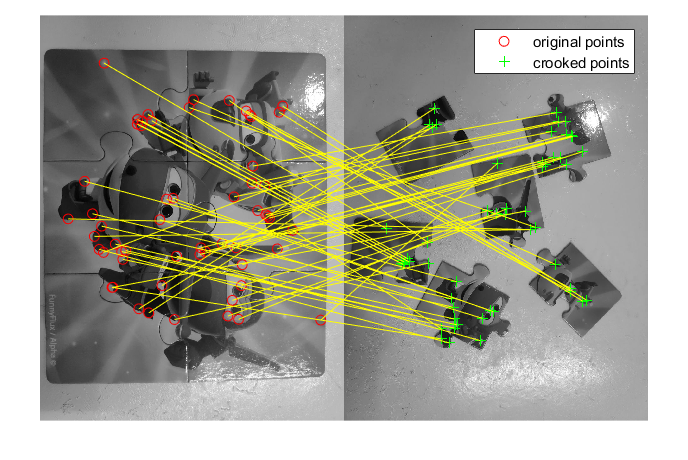

figure;
showMatchedFeatures(original_image,not,matchedPoints1,matchedPoints2,'montage');
legend('original points','crooked points');